%cd('/Users/yarinms/marvin/LAST.01.04.03/2024/08/11/proc')

cd('/Volumes/Extreme SSD/YS_data/LAST.01.04.01/2024/08/11')
List = MatchedSources.rdirMatchedSourcesSearch('FileTemplate','*.hdf5');

FN = 'Test20s';
if exist("List","var")
    flag =1;
end


Args.MagField = {'MAG_PSF'}; Args.MagErrField = {'MAGERR_PSF'};
Args.BadFlags = {'Saturated','Negative','NaN' ,'Spike','Hole','CR_DeltaHT','NearEdge'};
Args.EdgeFlags = {'Overlap'};
Args.runMeanFilterArgs      = {'Threshold',5, 'StdFun','OutWin'};
Args.Nvisits = 1;
Args.Ndet = 14*Args.Nvisits;


list = List;
%Args.Ndet = 16*Args.Nvisits;

  mB1725_175 =zeros(24,6);
 mB17_1725 =zeros(24,6);

 mB175_18 =zeros(24,6);
 mB18_185 =zeros(24,6);
 mB185_19 =zeros(24,6);
 mB19_195 =zeros(24,6);
 mB1195=zeros(24,6);
 FRD1=zeros(24,1);
 FRD2=zeros(24,1);
 FRD3=zeros(24,1);

  nB17_175 =zeros(24,6);
 nB175_18 =zeros(24,6);
 nB18_185 =zeros(24,6);
 nB185_19 =zeros(24,6);
 nB19_195 =zeros(24,6);
 nB1195=zeros(24,6);

bm17_172 =zeros(24,6);
bm172_174 =zeros(24,6);
bm174_176 =zeros(24,6);
bm176_178 =zeros(24,6);
bm178_18 =zeros(24,6);
bm18_182 =zeros(24,6);
bm182_184 =zeros(24,6);
bm184_186 =zeros(24,6);
bm186_188 =zeros(24,6);
bm188_19 =zeros(24,6);
bm19_192 =zeros(24,6);
bm192_194 =zeros(24,6);
bm194_196 =zeros(24,6);

bn17_172 =zeros(24,6);
bn172_174 =zeros(24,6);
bn174_176 =zeros(24,6);
bn176_178 =zeros(24,6);
bn178_18=zeros(24,6);
bn18_182=zeros(24,6);
bn182_184=zeros(24,6);
bn184_186=zeros(24,6);
bn186_188=zeros(24,6);
bn188_19=zeros(24,6);
bn19_192=zeros(24,6);
bn192_194=zeros(24,6);
bn194_196=zeros(24,6);


Mex17s2 = [];
Mex18s2 = [];
Mex19s2 = [];






Fap =zeros(24,6);
allSrcStat = zeros(24,6);
allSrcN = zeros(24,6);
h = waitbar(0);
detEff = [];
mEff = [];
AllFap = [];
AllS = 0;
tic
for Iid = 1:24 



    list1.FileName = List(Iid).FileName(contains(List(Iid).FileName,FN));
    list1.Folder   = List(Iid).Folder(contains(List(Iid).FileName,FN));
    list1.CropID = List(Iid).CropID;
    ms1 =  MatchedSources.readList(list1);
    Nvis = length(ms1);


    for Ivis = 1: length(ms1)
    

        MMS = ms1(Ivis).setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
        R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
        [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
        % Remove sources with NdetGood<MinNdet
        NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);

        Fndet    = NdetGood>Args.Ndet;

        % Fndet  = Fndet & (mean(MMS.Data.MAG_PSF,'omitnan') < 19.5);
        allSrc  = MMS.Nsrc;
        goodSrc = sum(Fndet);
        allSrcStat(Iid,Ivis) = goodSrc/allSrc;
        allSrcN(Iid,Ivis) = allSrc;

        % MagBinStat
        flag1 = mean(MMS.Data.MAG_PSF,'omitnan') > 17 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.5;
        mB17_175(Iid,Ivis) = sum(Fndet & flag1)/sum(flag1);
        flag2 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 18;
        mB175_18(Iid,Ivis) = sum(Fndet & flag2)/sum(flag2);
        flag3 = mean(MMS.Data.MAG_PSF,'omitnan') > 18 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.5;
        mB18_185(Iid,Ivis) = sum(Fndet & flag3)/sum(flag3);
        flag4 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 19;
        mB185_19(Iid,Ivis) = sum(Fndet & flag4)/sum(flag4);
        flag5 = mean(MMS.Data.MAG_PSF,'omitnan') > 19 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.5;
        mB19_195(Iid,Ivis) = sum(Fndet & flag5)/sum(flag5);
        flag6 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.5 ;
        mB1195(Iid,Ivis) = sum(Fndet & flag6)/sum(flag6);

        
        nB17_175(Iid,Ivis) = sum(flag1);
       
        nB175_18(Iid,Ivis) = sum(flag2);

        nB18_185(Iid,Ivis) = sum(flag3);

        nB185_19(Iid,Ivis) = sum(flag4);

        nB19_195(Iid,Ivis) = sum(flag5);

        nB1195(Iid,Ivis) = sum(flag6);


                % MagBinStat
           Flag1 = mean(MMS.Data.MAG_PSF,'omitnan') > 17 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.2;
        bm17_172(Iid,Ivis) = sum(Fndet & Flag1)/sum(Flag1);
        Flag2 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.2 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.4;
        bm172_174(Iid,Ivis) = sum(Fndet & Flag2)/sum(Flag2);
        Flag3 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.4 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.6;
        bm174_176 (Iid,Ivis) = sum(Fndet & Flag3)/sum(Flag3);
        Flag4 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.6 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.8;
        bm176_178(Iid,Ivis) = sum(Fndet & Flag4)/sum(Flag4);
        Flag5 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.8 & mean(MMS.Data.MAG_PSF,'omitnan') < 18;
        bm178_18(Iid,Ivis) = sum(Fndet & Flag5)/sum(Flag5);
        Flag6 = mean(MMS.Data.MAG_PSF,'omitnan') > 18 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.2;
        bm18_182(Iid,Ivis) = sum(Fndet & Flag6)/sum(Flag6);
        Flag7 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.2 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.4;
        bm182_184(Iid,Ivis) = sum(Fndet & Flag7)/sum(Flag7);
        Flag8 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.4 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.6;
        bm184_186(Iid,Ivis) = sum(Fndet & Flag8)/sum(Flag8);
        Flag9 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.6 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.8;
        bm186_188(Iid,Ivis) = sum(Fndet & Flag9)/sum(Flag9);
        Flag10 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.8 & mean(MMS.Data.MAG_PSF,'omitnan') < 19;
        bm188_19(Iid,Ivis) = sum(Fndet & Flag10)/sum(Flag10);
        Flag11 = mean(MMS.Data.MAG_PSF,'omitnan') > 19 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.2;
        bm19_192(Iid,Ivis) = sum(Fndet & Flag11)/sum(Flag11);
        Flag12 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.2 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.4;
        bm192_194(Iid,Ivis) = sum(Fndet & Flag12)/sum(Flag12);
        Flag13 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.4 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.6;
        bm194_196(Iid,Ivis) = sum(Fndet & Flag13)/sum(Flag13);



        if Ivis ==4

            Mex17s2 = [Mex17s2 , MMS.Data.MAG_PSF(:,Fndet &Flag5),MMS.Data.MAG_PSF(:,Fndet &Flag2)];
            Mex18s2 = [Mex18s2 , MMS.Data.MAG_PSF(:,Fndet &Flag7),MMS.Data.MAG_PSF(:,Fndet &Flag8)];
            Mex19s2 = [Mex19s2 , MMS.Data.MAG_PSF(:,Fndet &Flag11),MMS.Data.MAG_PSF(:,Fndet &Flag12)];


        end



        
        bn17_172(Iid,Ivis) = sum(Flag1);
       
        bn172_174(Iid,Ivis) = sum(Flag2);

        bn174_176(Iid,Ivis) = sum(Flag3);

        bn176_178(Iid,Ivis) = sum(Flag4);

        bn178_18(Iid,Ivis) = sum(Flag5);

        bn18_182(Iid,Ivis) = sum(Flag6);
        bn182_184(Iid,Ivis) = sum(Flag7);
       
        bn184_186(Iid,Ivis) = sum(Flag8);

        bn186_188(Iid,Ivis) = sum(Flag9);

        bn188_19(Iid,Ivis) = sum(Flag10);

        bn19_192(Iid,Ivis) = sum(Flag11);

        bn192_194(Iid,Ivis) = sum(Flag12);
        bn194_196(Iid,Ivis) = sum(Flag13);


        

        indices = find(flag1 == 1);


        MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);

        light_curves = MMS.Data.MAG_PSF;
        [Nan,consecutive_nan_indices,FAP,mFap,Si,T] = X.find_similar_nan_patterns(light_curves);

        % Nan Count:
        M = median(light_curves,'omitnan')';
        N = sum(isnan(light_curves(:,:)));

        AllFap = [AllFap ; M(logical(FAP))];
        AllS   = AllS+numel(M);


        Npts = MMS.Nepoch;
        detEff = [detEff;1 - N'/Npts];
        mEff = [mEff;M];
        c=0;
        for j = 1 : size(Nan,2)
            c = c + length(Nan{1,j}{1}{2});
        end

        Fap(Iid,Ivis)   = sum(FAP)/length(light_curves(1,:));
        MFap(Iid,Ivis)  = sum(sum(mFap))/(2* length(FAP));
        t(Iid,Ivis)     = T;

        if Ivis == 454
        [fDetection1,fDetection2,fDetection3] = detect3(MMS);
          

        FRD1(Iid,1) = size(fDetection1,1)/MMS.Nsrc;
        FRD2(Iid,1) = size(fDetection2,1)/MMS.Nsrc;
        FRD3(Iid,1) = size(fDetection3,1)/MMS.Nsrc;
        end
     


        
     waitbar(Iid/24,h,sprintf('%i / %i Visits analayzed',(Iid*Ivis),(24*Nvis)))

    end

 



end
close(h)
toc

Elapsed time is 269.391737 seconds.




fprintf('The False Positive rate as a result of minimum 2 consecutive NaNs in a 20s exposure :%.4f',mean(mean(Fap(:,3:end),'omitnan'),'omitnan'))

The False Positive rate as a result of minimum 2 consecutive NaNs in a 20s exposure :0.0447

fprintf('Out of these events, %.4f appear in control group stars',mean(mean(MFap(:,3:end),'omitnan'),'omitnan'))

Out of these events, 0.0611 appear in control group stars

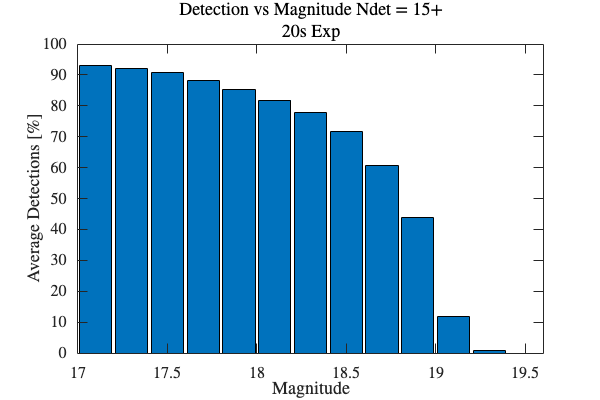




binEdges = linspace(17.0,20, 30);
binEfficiencies(1) = median(median(mB17_175))*100;
binEfficiencies(2) = median(median(mB175_18))*100;
binEfficiencies(3) = median(median(mB18_185,'omitnan'))*100;
binEfficiencies(4) = median(median(mB185_19,'omitnan'))*100;
binEfficiencies(5) = median(median(mB19_195,'omitnan'))*100;
binEfficiencies(6) = median(median(mB1195))*100;


bbinE(1) = median(median(bm17_172,'omitnan'))*100;
bbinE(2) = median(median(bm172_174,'omitnan'))*100;
bbinE(3) = median(median(bm174_176,'omitnan'))*100;
bbinE(4) = median(median(bm176_178,'omitnan'))*100;
bbinE(5) = median(median(bm178_18,'omitnan'))*100;
bbinE(6) = median(median(bm18_182,'omitnan'))*100;
bbinE(7) = median(median(bm182_184,'omitnan'))*100;
bbinE(8) = median(median(bm184_186,'omitnan'))*100;
bbinE(9) = median(median(bm186_188,'omitnan'))*100;
bbinE(10) = median(median(bm188_19,'omitnan'))*100;
bbinE(11) = median(median(bm19_192,'omitnan'))*100;
bbinE(12) = median(median(bm192_194,'omitnan'))*100;
bbinE(13) = median(median(bm194_196,'omitnan'))*100;





binCenters =[17.1,17.3,17.5,17.7,17.9,18.1,18.3,18.5,18.7,18.9,19.1,19.3,19.5];



% Plot the histogram
figure('Position', [100, 100, 600, 400]);
bar(binCenters, bbinE,"BarWidth",0.9,"BarLayout","stacked");
xlabel('Magnitude');
ylabel('Average Detections [%]');
title(sprintf('Detection vs Magnitude Ndet = 15+\n 20s Exp'));
xlim([17,19.6])


fprintf('All sources in all visits:')

All sources in all visits:

fprintf('%.2f%% out of %i sources survived ',median(median(allSrcStat))*100,sum(sum(allSrcN)))

70.93% out of 2413405 sources survived 


$$17<M<17\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB17_175))*100,sum(sum(nB17_175)))

92.40% out of 272812 sources survived 


$$17\ldotp 5<M<18$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB175_18))*100,sum(sum(nB175_18)))

87.69% out of 315432 sources survived 


$$18<M<18\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB18_185),'omitnan')*100,sum(sum(nB18_185)))

78.48% out of 341385 sources survived 


$$18\ldotp 5<M<19$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB185_19),'omitnan')*100,sum(sum(nB185_19)))

55.23% out of 360934 sources survived 


$$19<M<19\ldotp 5$$


fprintf('%.2f%% of %i sources survived ',median(median(mB19_195),'omitnan')*100,sum(sum(nB19_195)))

11.07% of 236524 sources survived 


$$19\ldotp 5<M$$


fprintf('%.2f%% of  %i sources survived ',median(median(mB1195),'omitnan')*100,sum(sum(nB1195)))

0.00% of  20772 sources survived 